# Progetto Controlli Automatici

## Esperimenti Equilibrio

clc
clear
close all

addpath(genpath("..\"));

set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

load("modello\data.mat");
warning("off" , "all");
load_system("modello\model.mdl");

N = length(time);
Ts = time(2) - time(1);

colori = lines(2);

Simulazione con i segnali dati:

sim("model");

i = 1

figure;
subplot(2 , 1 ,1);
plot(time , y , Color=colori(1 , :));
ylabel("Angolo Ginocchio")
grid on;
subplot(2 , 1 , 2);
plot(time , u , Color=colori(2 , :));
ylabel("pwm $[\mu s]$");
xlabel("Temp $[s]$");
grid on;

#### Test di diverse intensita:

pw = [zeros(201,1); 25 * ones(200 , 1) ; 50 * ones(200 , 1);
75* ones(200 , 1);100 * ones(200 , 1); linspace(100 , 120 , 200)';
120*ones(800 , 1)];
sim("model");

i = 1

figure
subplot(2 , 1 , 1);
plot(time , y , DisplayName="Angolo Ginocchio" , Color=colori(1 , :));
ylim([80 180]);
ylabel("Angolo Ginocchio");
xlabel("Temp $[s]$");
grid on

subplot(2 , 1 , 2);
plot(time , u , DisplayName="PWM" , Color=colori(2 , :));
ylim([0 150]);
ylabel("PWM $[\mu s]$");
xlabel("Temp $[s]$");
grid on

## Si sceglie un punto di equliblio a $135\degree $

Risposta allo scalino:

pw_eq = 121.35;

pw = [zeros(10/Ts , 1) ;            % 10 secondi a 0
        pw_eq * ones(20/Ts , 1);    % 20 secondi a 121.35
        zeros(70/Ts +1 , 1)];
sim("model");

i = 1

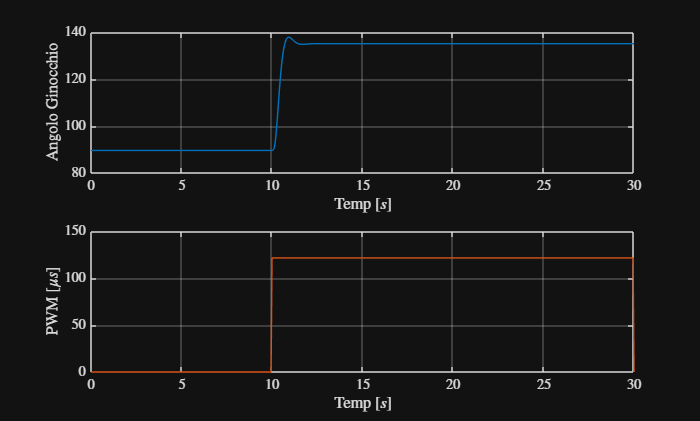

figure
subplot(2 , 1 , 1);
plot(time , y , DisplayName="Angolo Ginocchio" , Color=colori(1 , :));
ylabel("Angolo Ginocchio");
xlabel("Temp $[s]$");
xlim([0 30])
grid on

subplot(2 , 1 , 2);
plot(time , u , DisplayName="PWM" , Color=colori(2 , :));
ylabel("PWM $[\mu s]$");
xlabel("Temp $[s]$");
xlim([0 30])
grid on

#### Osservazione del ritardo puro d'ingresso

Si trovano circa $5 /10\mu s$ di ritardo che corrsipondono a $1/2 $passi di simulazione:

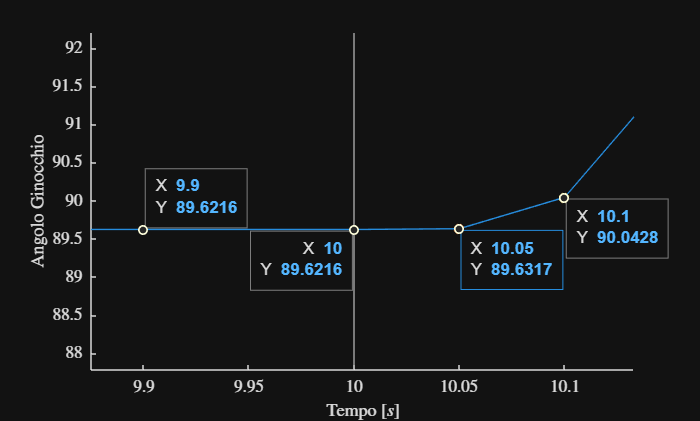

figure;
indice_inizio = floor(9.95/Ts);
indice_fine = floor(10.5/Ts);
intervallo = indice_inizio:indice_fine;
y_zoom = y(intervallo);
passo_1 = 202;
passo_2 = 203;
time_zoom = time(intervallo);
hold on
plot(time_zoom , y_zoom);
plot(time(passo_1) , y(passo_1) , Marker="x" , LineWidth=3);
plot(time(passo_2) , y(passo_2) , Marker="x" , LineWidth=3);
xline(10)
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
hold off;

xlim([9.875 10.133])
ylim([87.78 92.21])
 
hDataTip = findobj(gca,"DataIndex",1);
set(hDataTip,"Location","northwest");
ax2 = gca;
chart = ax2.Children(2);
datatip(chart,10.1,89.95,"Location","southeast");
chart = ax2.Children(4);
datatip(chart,10,89.62,"Location","southwest");
datatip(chart,9.9,89.62,"Location","northeast");
chart = ax2.Children(3);
datatip(chart,10.05,89.63,"Location","southeast");

# **Identificazione**

Si vuole controllare l'angolo nell'introno $\pm 10\degree $ rispetto all'equilibrio ($125\degree $, $145\degree $) si è scelto di creare 3 segnali diversi per l'input:

- Randomico a blocchi costanti di $5s$ con valori compresi tra $117\ldotp 5\mu s$ e $127.1 \mu s$;

- PRBS con ampiezza $117\ldotp 5\mu s$ e $127.1 \mu s$;  

- Vaolori randomici tra $117\ldotp 5\mu s$ e $127.1 \mu s
$ a blocchi con tempi variabili tra $0\ldotp 5s$ e $5s$.

pw_max = 127.1;
pw_min = 117.5;

% i primi tre secondi tolti poiché il segnale non è stazionario in quel
% periodo
primi_secondi = 3/0.05;
time_ridotto = time(primi_secondi:end);

### Randomico a blocchi costanti di $5s\;\;$con valori compresi tra $117\ldotp 5\mu$ e $127.1 \mu$

load("pw_1.mat");

pw = pw_1;
sim("model");

i = 1

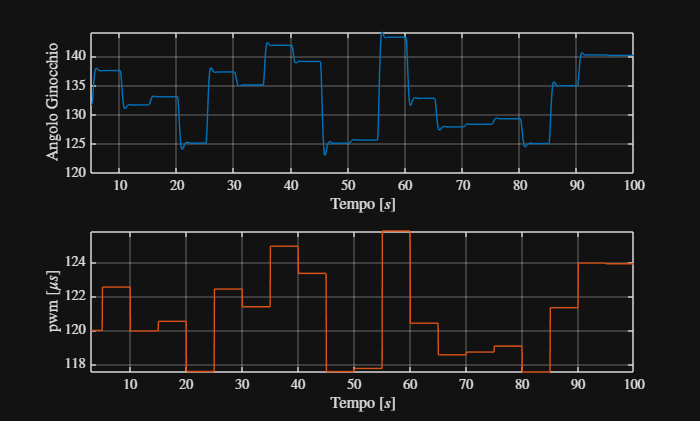

y_1 = y(primi_secondi:end);
y_1_media = mean(y_1);
y_1_no_media = y_1 - y_1_media;
pw_1 = pw_1(primi_secondi:end);
pw_1_media = mean(pw_1);
pw_1_no_media = pw_1 - pw_1_media;
figure;
subplot(2 , 1 , 1);
plot(time_ridotto , y_1, Color = colori(1 ,:));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([5 100])
grid on;
subplot(2 , 1 , 2);
plot(time_ridotto , pw_1, Color = colori(2 ,:));
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")
xlim([3 100])
grid on

### PRBS con ampiezza $117\ldotp 5\mu$ e $127.1 \mu$

range_PRBS = [0 1];
pw_2 = idinput(N , 'prbs' , range_PRBS , [pw_min , pw_max]);
pw = pw_2;

sim("model");

i = 1

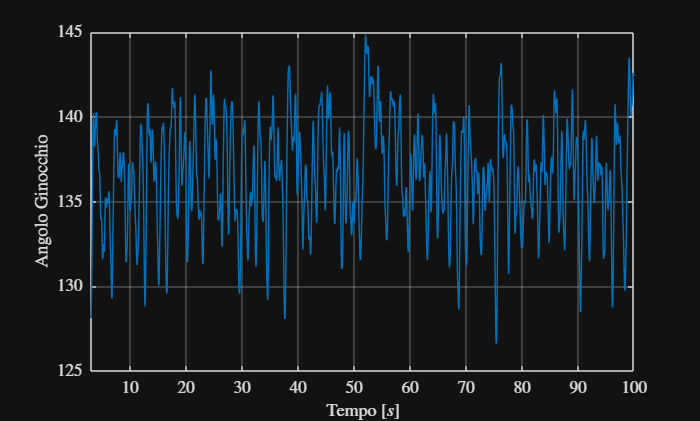

y_2 = y(primi_secondi:end);
y_2_media = mean(y_2);
y_2_no_media = y_2 - y_2_media;
pw_2 = u(primi_secondi:end);
pw_2_media = mean(pw_2);
pw_2_no_media = pw_2 - pw_2_media;
figure;
subplot(1 , 1 , 1);
plot(time_ridotto , y_2, Color = colori(1 ,:));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([3 100])
grid on;

% subplot(2 , 1 , 2);
% plot(time_ridotto , pw_2, Color = colori(2 ,:));
% ylabel("pwm $[\mu s]$")
% xlabel("Tempo $[s]$")
% xlim([3 100])
% grid on

### Vaolori randomici tra $117\ldotp 5\mu$ e $127.1 \mu$ a blocchi con tempi variabili tra $0\ldotp 5s$ e $5s$

load("pw_3.mat");
pw = pw_3;
sim("model");

i = 1

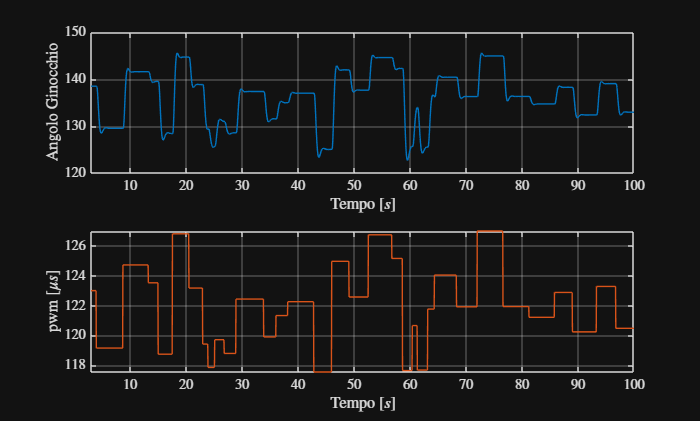

y_3 = y(primi_secondi:end);
y_3_media = mean(y_3);
y_3_no_media = y_3 - y_3_media;
pw_3 = u(primi_secondi:end);
pw_3_media = mean(pw_3);
pw_3_no_media = pw_3 - pw_3_media;
figure;
subplot(2 , 1 , 1);
plot(time_ridotto , y_3 , Color=colori(1 , :));
ylabel("Angolo Ginocchio");
xlabel("Tempo $[s]$")
xlim([3 100])
grid on;
subplot(2 , 1 , 2);
plot(time_ridotto , pw_3 , Color=colori(2 , :));
ylabel("pwm $[\mu s]$")
xlabel("Tempo $[s]$")
xlim([3 100])
grid on

## Identificazione del Modello

### Si utilizza il segnale randomico a blocchi costanti di $5s$

% Divisione del data set 70% e 30%
N = length(y_1);

n_70 = floor(N*0.7);
y_modello = y_1_no_media(1:n_70);
u_modello = pw_1_no_media(1:n_70);

data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30% del primo set
n_30 = N - n_70;

y_val = y_1_no_media(1:n_30);
u_val = pw_1_no_media(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
n_ar = 4;
n_x = 3;
n_ma = 1;
k = 2;

%Sima del modello
modello_armax_1 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_1 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)      
  A(z) = 1 - 3.302 z^-1 + 4.151 z^-2 - 2.365 z^-3 + 0.5178 z^-4
                                                               
  B(z) = 0.02173 z^-2 + 0.01109 z^-3 - 0.03018 z^-4            
                                                               
  C(z) = 1 + 0.8285 z^-1                                       
                                                               
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=3   nc=1   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.96% (prediction focus)      
FPE: 4.77e-06, MSE: 4.686e-06                          
 


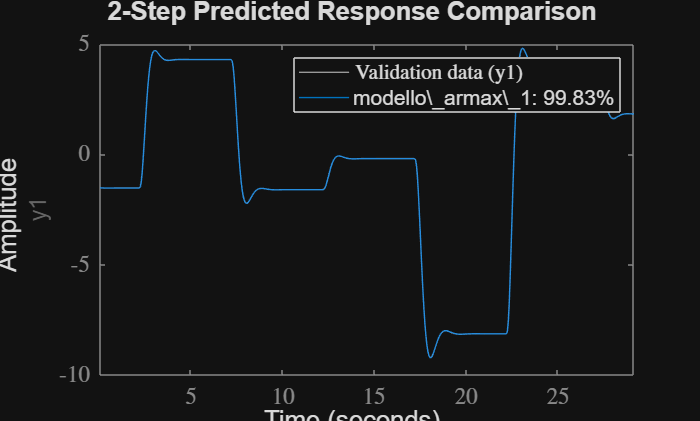

figure
compare(data_val, modello_armax_1 , k);

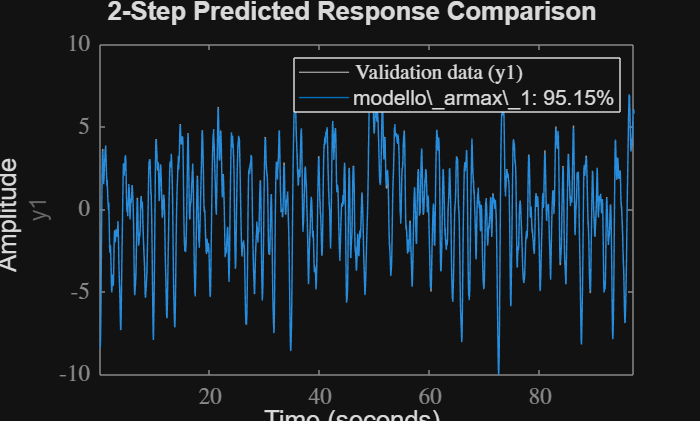

% Validazione con gli altri set
y_val = y_2_no_media;
u_val = pw_2_no_media;

data_val = iddata(y_val , u_val , Ts);
figure

compare(data_val, modello_armax_1 , k);

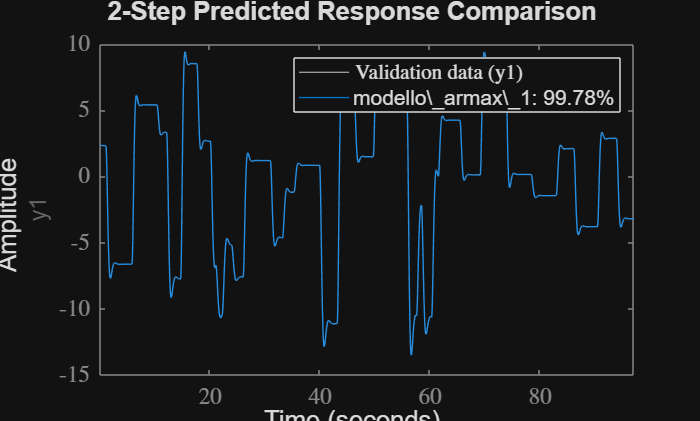

y_val = y_3_no_media;
u_val = pw_3_no_media;

data_val = iddata(y_val , u_val , Ts);

compare(data_val, modello_armax_1 , k);

## Si utilizza il segnale PRBS

% 70% dei dati
y_modello = y_2(1:n_70);
u_modello = pw_2(1:n_70);

data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30% del secondo set
n_30 = N - n_70;

y_val = y_2_no_media(1:n_30);
u_val = pw_2_no_media(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
% n_ar = 5;
% n_x = 3;
% n_ma = 1;
% k = 2;

%Stima del modello
modello_armax_2 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_2 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)      
  A(z) = 1 - 2.861 z^-1 + 3.244 z^-2 - 1.777 z^-3 + 0.4167 z^-4
                                                               
  B(z) = 0.02011 z^-2 + 0.02032 z^-3 - 0.01568 z^-4            
                                                               
  C(z) = 1 + 0.6552 z^-1                                       
                                                               
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=3   nc=1   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.21% (prediction focus)      
FPE: 0.000634, MSE: 0.0006229                          
 


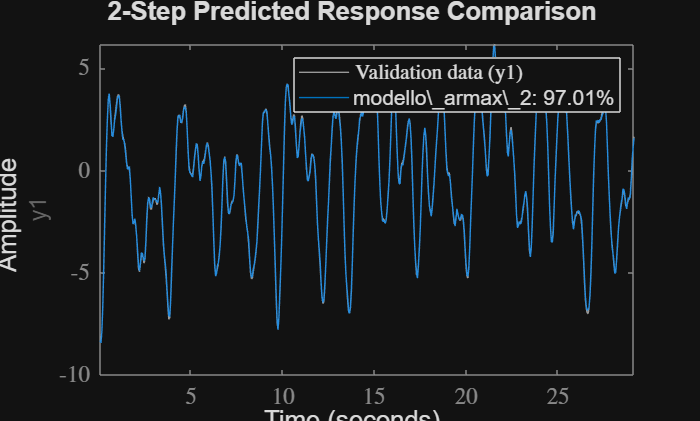

figure
compare(data_val, modello_armax_2 , k);

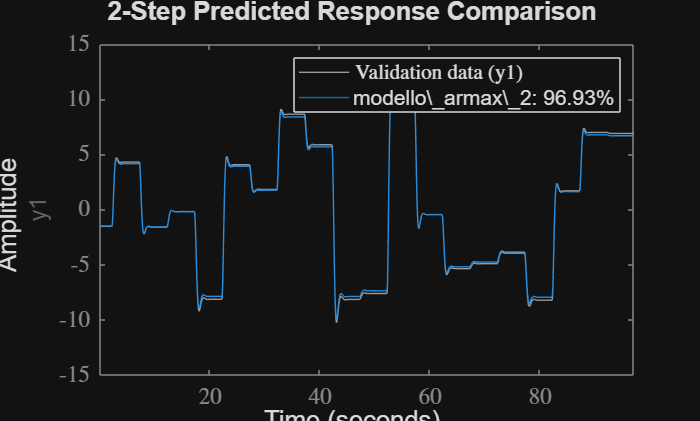


% Validazione con gli altri set
y_val = y_1_no_media;
u_val = pw_1_no_media;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_2 , k)

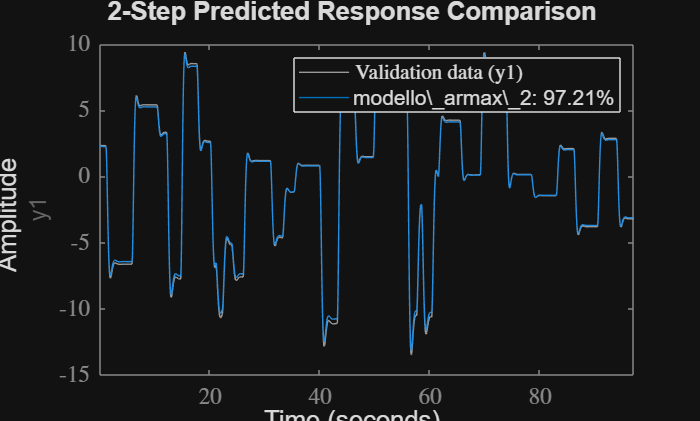

% Validazione con il terzo set
y_val = y_3_no_media;
u_val = pw_3_no_media;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_2 , k)

## Si utilizza il segnale randomico a blocchi variabili

% 70% dei dati
n_70 = floor(N*0.7);
y_modello = y_3_no_media(1:n_70);
u_modello = pw_3_no_media(1:n_70);


data_ident = iddata(y_modello , u_modello , Ts);

% Validazione con il 30%
n_30 = N - n_70;

y_val = y_3_no_media(1:n_30);
u_val = pw_3_no_media(1:n_30);

data_val = iddata(y_val , u_val , Ts);

%definizione ordini AR MA X e K
% n_ar = 5;
% n_ma = 1;
% n_x = 3;
% k = 2;

%Sima del modello
modello_armax_3 = armax(data_ident , [n_ar n_x n_ma k])


modello_armax_3 =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)      
  A(z) = 1 - 3.278 z^-1 + 4.094 z^-2 - 2.319 z^-3 + 0.5051 z^-4
                                                               
  B(z) = 0.0217 z^-2 + 0.01175 z^-3 - 0.02997 z^-4             
                                                               
  C(z) = 1 + 0.7439 z^-1                                       
                                                               
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=3   nc=1   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.95% (prediction focus)      
FPE: 9.569e-06, MSE: 9.401e-06                         
 


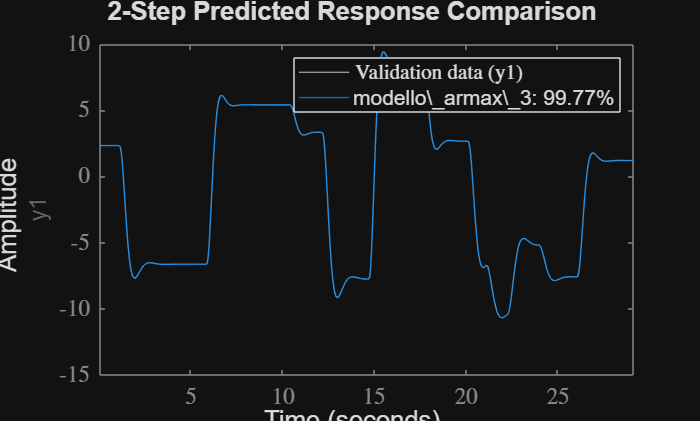

figure
compare(data_val, modello_armax_3 , k)

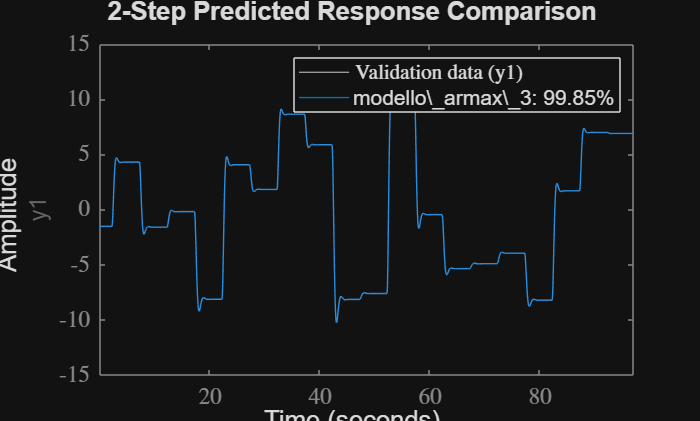


% Validazione con il primo set
y_val = y_1_no_media;
u_val = pw_1_no_media;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_3, k)

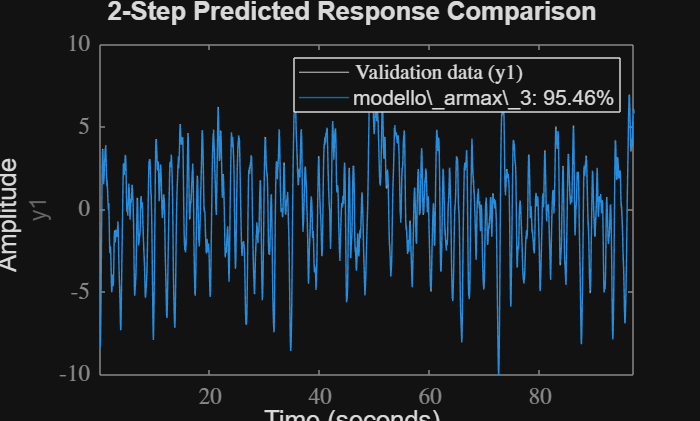

% Validazione con il secondo set
y_val = y_2_no_media;
u_val = pw_2_no_media;

data_val = iddata(y_val , u_val , Ts);
figure
compare(data_val, modello_armax_3 , k)

Di seguito si riportano i determinanti di $R^{\{i\}}_{uu}$ con $i$ il grado di persistenza eccitazione per i tre diversi segnali:

        1.Randomico a blocchi costanti:

gamma_uu = autocorr(pw_1_no_media, "NumLags", n_x);

for i = 1 : n_x+1
    R = toeplitz(gamma_uu(1:i));
    det_R_pw_1(i) = det(R);
end
det_R_pw_1

det_R_pw_1 =     1.0000    0.0175    0.0003    0.0000


        2. PRBS

gamma_uu = autocorr(pw_2_no_media, "NumLags", n_x);

for i = 1 : n_x+1
    R = toeplitz(gamma_uu(1:i));
    det_R_pw_2(i) = det(R);
end
display(det_R_pw_2);

det_R_pw_2 =     1.0000    0.9998    0.9997    0.9995


        3. Randomico a blocchi variabili:

gamma_uu = autocorr(pw_3_no_media, "NumLags", n_x);

for i = 1 : n_x+1
    R = toeplitz(gamma_uu(1:i));
    det_R_pw_3(i) = det(R);
end
display(det_R_pw_3);

det_R_pw_3 =     1.0000    0.0348    0.0012    0.0000


# Controllo a Minima Varianza

## Verifica Preliminare sulle radici di $B(z)$

modello = modello_armax_2;
modello


modello =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)      
  A(z) = 1 - 2.861 z^-1 + 3.244 z^-2 - 1.777 z^-3 + 0.4167 z^-4
                                                               
  B(z) = 0.02011 z^-2 + 0.02032 z^-3 - 0.01568 z^-4            
                                                               
  C(z) = 1 + 0.6552 z^-1                                       
                                                               
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=3   nc=1   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "data_ident".
Fit to estimation data: 99.21% (prediction focus)      
FPE: 0.000634, MSE: 0.0006229                          
 


abs(roots(modello.B))

ans =     1.5227
    0.5120


abs(roots(modello.A))

ans =     0.9336
    0.9336
    0.6915
    0.6915


## Lunga Divisione

####  
$$ \frac{C(z)}{A(z)} = E(z) + \frac{\widetilde{R}(z)}{A(z)}z^{-k}$$


[E , R] = LungaDivisione(modello.C , modello.A , k);
E = tf(E , 1 , Ts);
E.Variable = "z^-1";
E.Denominator = 1;
E


E =
 
  1 + 3.516 z^-1
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


R = tf(R , 1 , Ts);
R.Variable = "z^-1";
R.Denominator = 1;
R


R =
 
  6.817 - 9.629 z^-1 + 5.833 z^-2 - 1.465 z^-3
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties
